train_list = get_mp3_list('Songs\Train');
save('SONGID_DB.mat','train_list');
hashtable = zeros(2^21, 4);
save('HASHTABLE.mat','hashtable');

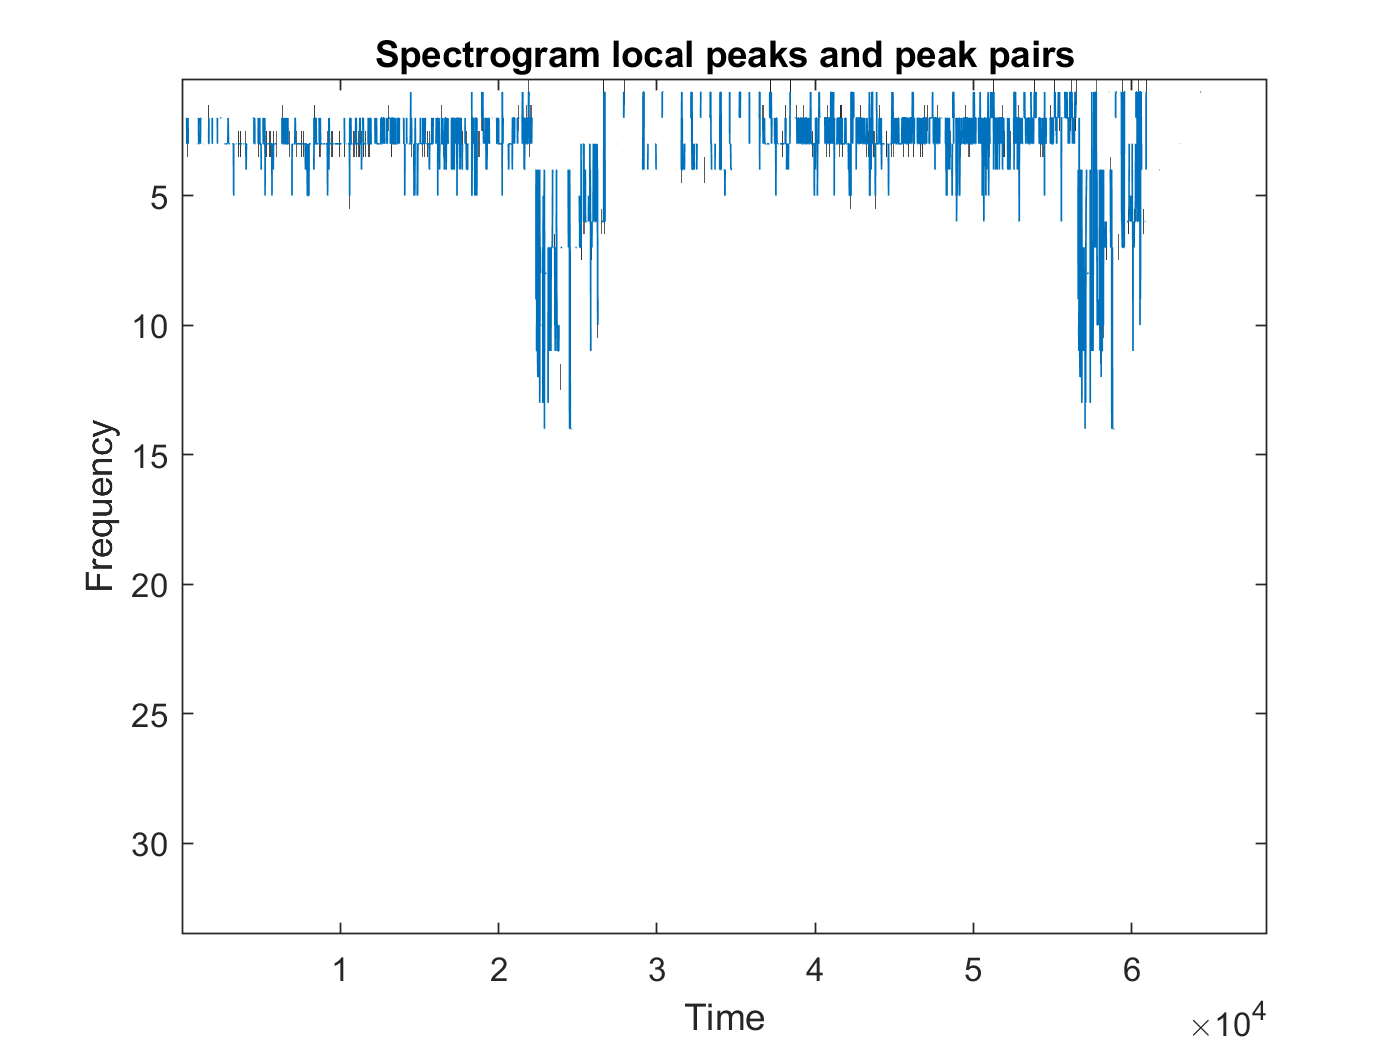

load('SONGID_DB.mat');
load('HASHTABLE.mat');
sid = 1;
[clip, fs] = audioread(char(train_list(1)));
r_peaks = voiceprint(clip, fs);
pair = peak_to_pair(r_peaks);


index = 2^16*(pair(:,2)-pair(:,1)) + 2^8*pair(:,3) + pair(:,4);
for i = 1:length(index)
    if hashtable(index(i),1) == 0
        hashtable(index(i),1) = sid;
        hashtable(index(i),2) = pair(i,1); 
    end
end
save('HASHTABLE.mat','hashtable');

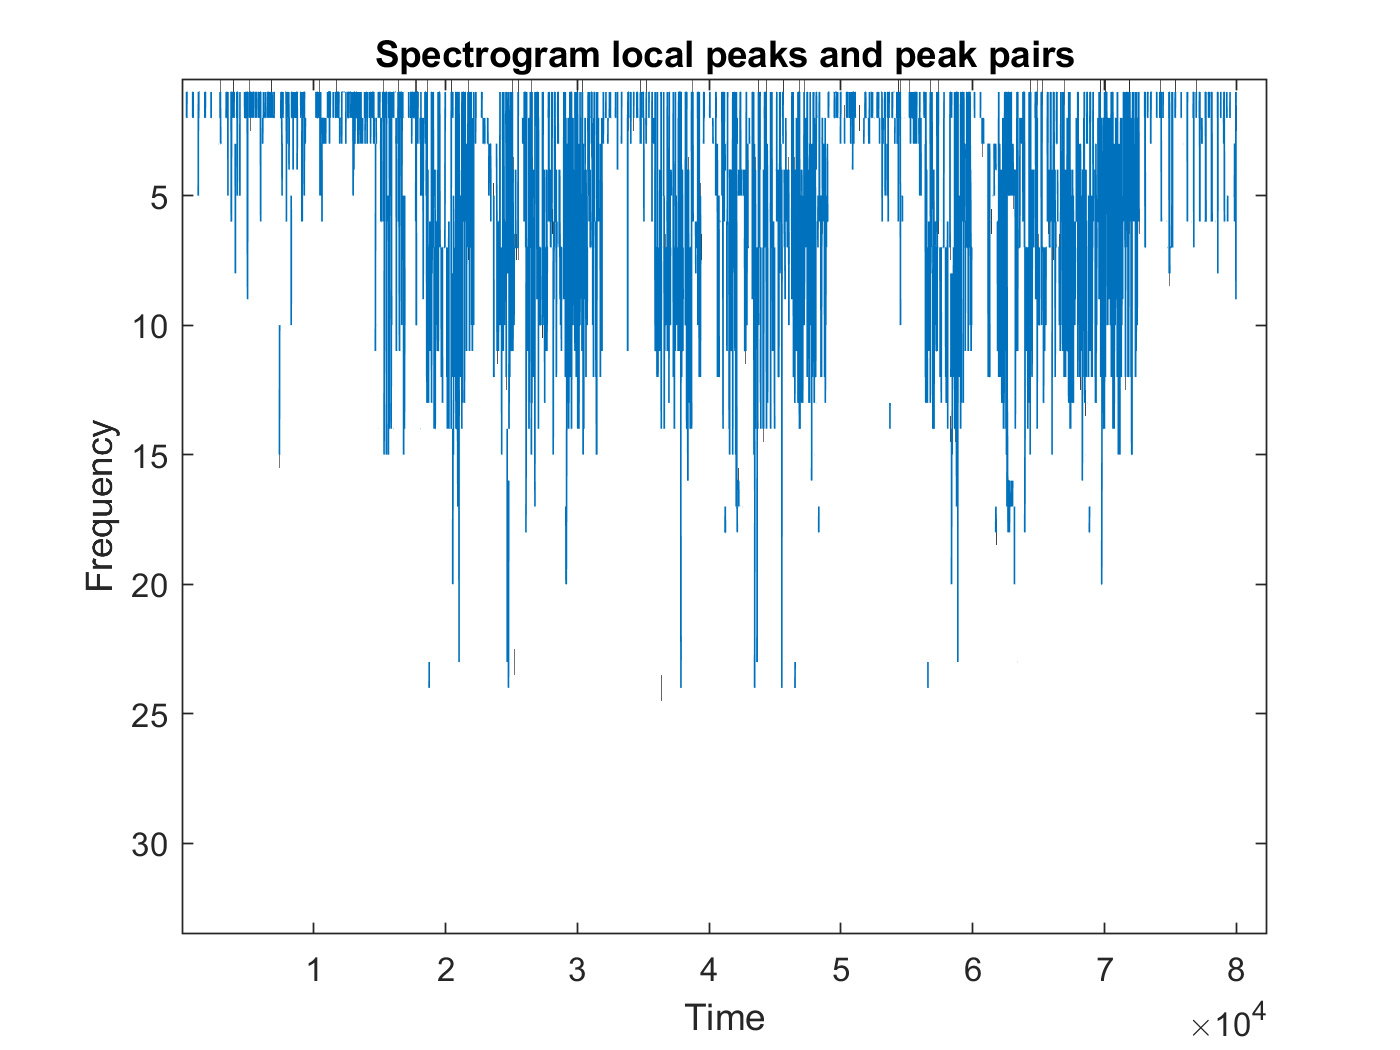

sid = 2;
[clip, fs] = audioread(char(train_list(2)));
r_peaks = voiceprint(clip, fs);
pair = peak_to_pair(r_peaks);


index = 2^16*(pair(:,2)-pair(:,1)) + 2^8*pair(:,3) + pair(:,4);
for i = 1:length(index)
    if hashtable(index(i),1) == 0
        hashtable(index(i),1) = sid;
        hashtable(index(i),2) = pair(i,1);
    elseif hashtable(index(i),3) == 0
        hashtable(index(i),3) = sid;
        hashtable(index(i),4) = pair(i,1);
    end
end
save('HASHTABLE.mat','hashtable');

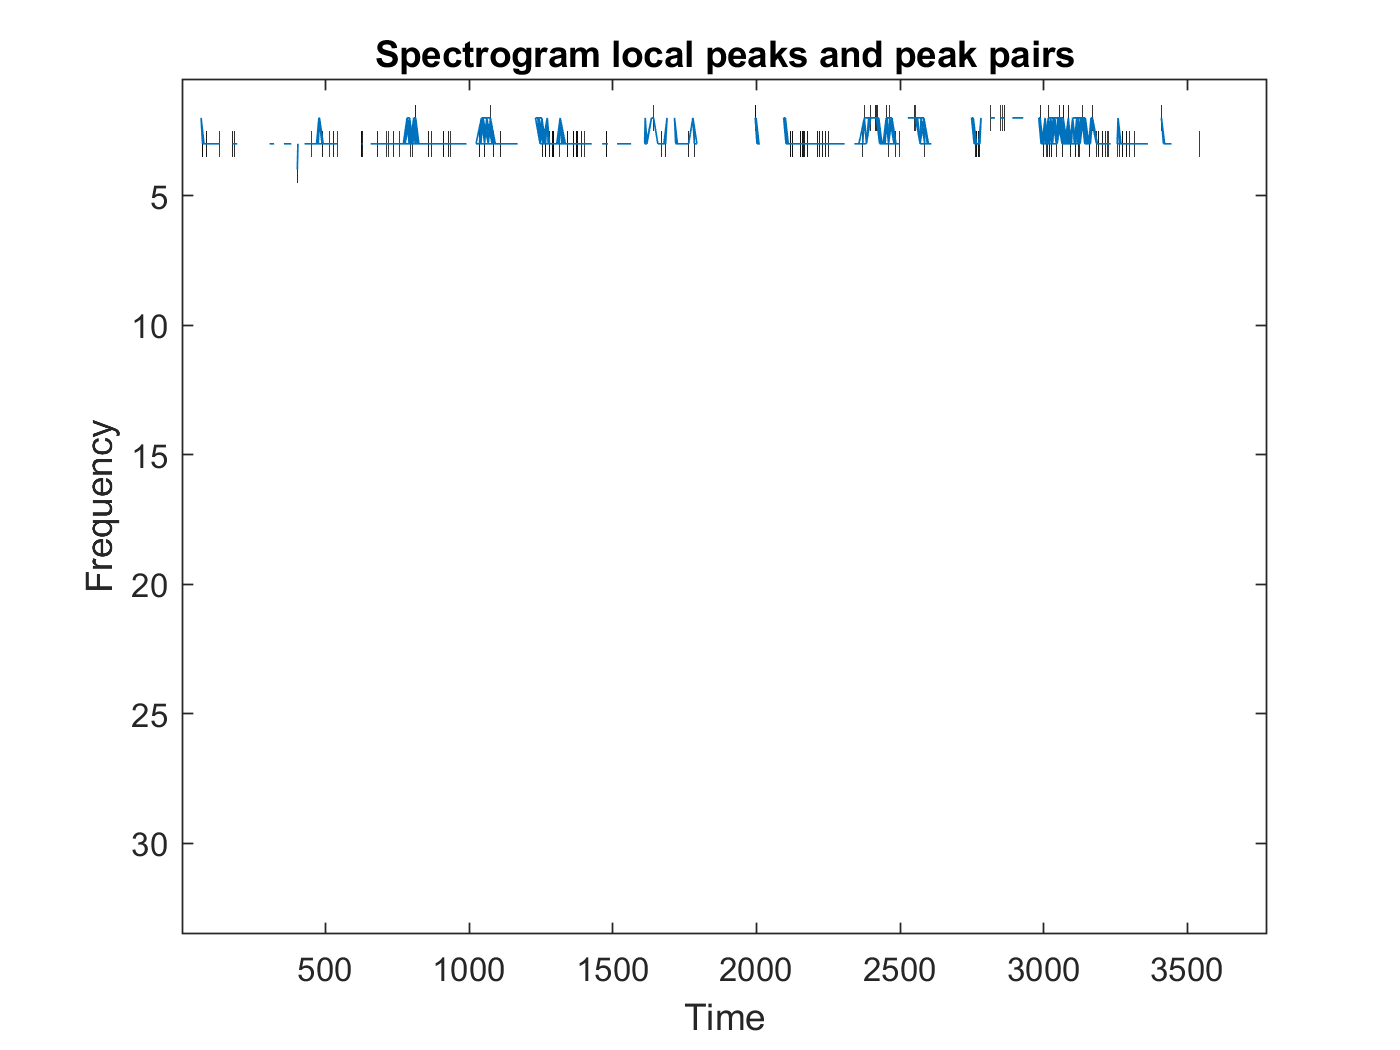

clip_list = get_mp3_list('Songs\Clips');
[clip, fs] = audioread(char(clip_list(2)));
r_peaks = voiceprint(clip, fs);
pair = peak_to_pair(r_peaks);

index = 2^16*(pair(:,2)-pair(:,1)) + 2^8*pair(:,3) + pair(:,4);
expected_id = [];
for i = 1:length(index)
    if hashtable(index(i),1) ~= 0
        expected_id = [expected_id , hashtable(index(i),1)];
    end
    if hashtable(index(i),3) ~= 0
        expected_id = [expected_id , hashtable(index(i),3)];
    end
end
id = mode(expected_id)

id = 1

function song_list = get_mp3_list(directory)
  dir_object = dir(directory);

  full_list = cell(size(dir_object));
  for i=1:size(dir_object,1)
    full_list{i} = dir_object(i).name;
  end
  
  song_list = cell(size(full_list));
  counter=1;
  for ii = 1 : size(full_list, 1)
    if ~isempty(strfind(full_list{ii}, '.mp3'))
      song_list{counter} = full_list{ii};
      counter = counter + 1;
    end
  end
  if counter == 1
    disp('No MP3s Found'); 
  end
  
  % Reduce list to correct length
  song_list = song_list(1:counter-1);
end

function pairs = peak_to_pair(peaks)

    deltaT = 20; % Time interval after the peak. (in pixels)
    deltaF = 10; % Distance from the frequency of the peak. (in pixels)
    plotLines = true;
    timeLowerBound = 0;
    fanout = 3;
    timeUpperBound = timeLowerBound + deltaT;

    [f, t] = find(peaks);
    numOfPeaks = length(f);

    outputTuple = [];

    wb = waitbar(0,'1','Name','Number of Peaks');
    for p = 1 : numOfPeaks
        waitbar(p/numOfPeaks,wb,sprintf('%d : %d',p, numOfPeaks))
        currentPeakF = f(p);
        currentPeakT = t(p);
        peakPairPosition = (t ~= t(p)) & ...
                           (f > currentPeakF - deltaF) & ...
                           (f < currentPeakF + deltaF) & ...
                           (t > currentPeakT + timeLowerBound) & ...
                           (t < currentPeakT + timeUpperBound);
        peakPairPosition = find(peakPairPosition, fanout);
        tuple = cat(2, repmat(t(p), size(peakPairPosition)), t(peakPairPosition), ...
                       repmat(f(p), size(peakPairPosition)), f(peakPairPosition));
        outputTuple = cat(1, outputTuple, tuple);
    end
    close(wb);
    pairs = outputTuple;

    if plotLines
        figure
        imagesc(peaks)
        colormap(1 - gray)
        hold on
        for i = 1 : size(pairs, 1)
            line(pairs(i, 1:2), pairs(i, 3:4))
        end
        title('Spectrogram local peaks and peak pairs')
        xlabel('Time')
        ylabel('Frequency')
    end
end

function reduced_peaks = voiceprint(clip, fs)
    if size(clip,2) == 2
        clip = mean(clip,2);
    end
    clip = clip - mean(clip);
    new_sample_rate = 8000;
    clip = resample( clip , new_sample_rate , fs ) ;
    window = 64;
    noverlap = 32;
    nfft = 64;
    [S, F, T] = spectrogram( clip , window, noverlap , nfft , new_sample_rate ) ;
    S = log10(abs(S));
    CS1 = circshift(S,[0, -1]);
    CS2 = circshift(S,[0, 1]);
    CS3 = circshift(S,[1, 0]);
    CS4 = circshift(S,[1, 1]);
    CS5 = circshift(S,[1, -1]);
    CS6 = circshift(S,[-1, 0]);
    CS7 = circshift(S,[-1, 1]);
    CS8 = circshift(S,[-1, -1]);
    P = ((S - CS1)> 0) & ((S - CS2)> 0) &((S - CS3)> 0) & ((S - CS4)> 0)&...
        ((S - CS5)> 0) & ((S - CS6)> 0) &((S - CS7)> 0) & ((S - CS8)> 0);
    peaks = P.*S;
    s_peaks = sort(reshape(peaks,[],1));
    th = (peaks -  s_peaks(end - round(T(end)*30)) > 0);
    reduced_peaks = th.*peaks;
end
